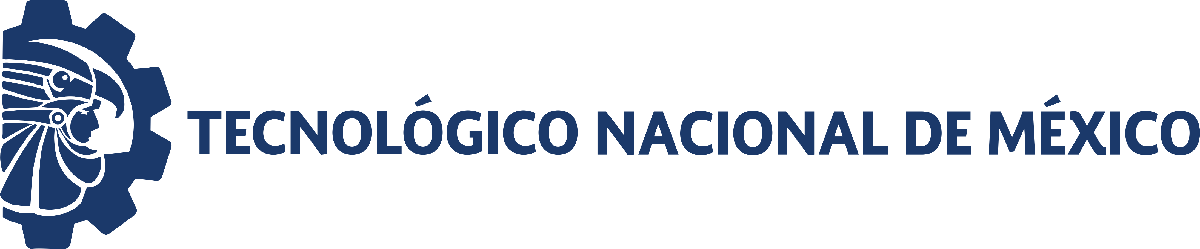                                 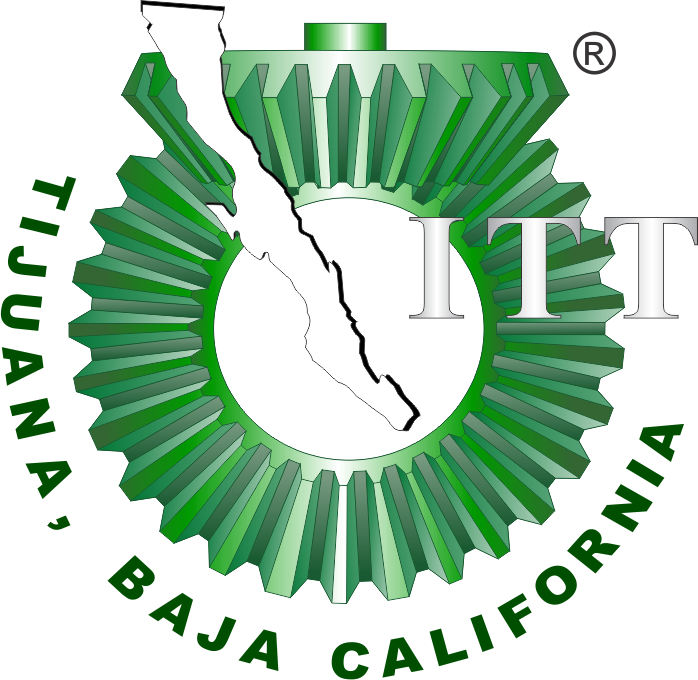

# Práctica 4: Regeneracion de Globulos Rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

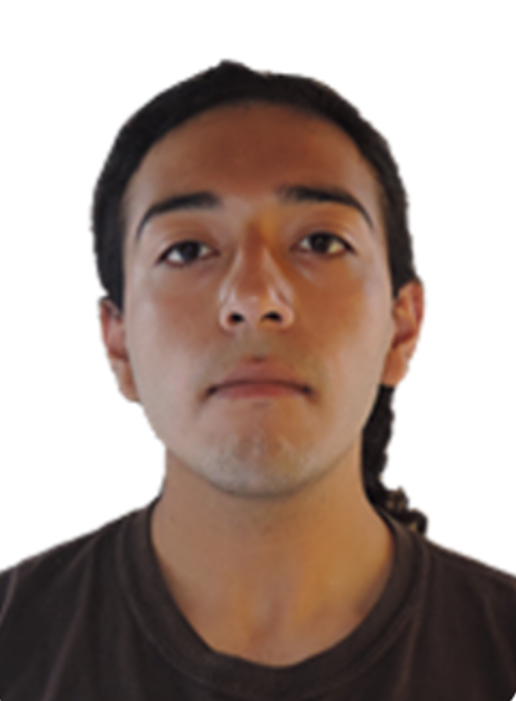

[Foto]

Nombre del alumno: **Andres Preciado Hernandez **

Número de control: **21210469**

Correo institucional: **l21210469@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de simulacion
dt = 1E-3; %Intervalo para el metodo de solucion por diferencias finitas 
n = round(tend/dt);%Cantidad de interaciones para el metodo numerico 
% Condiciones iniciales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885; 
%Parametos partuculaers a cassa paciente 
gamma = [0.796, 0.388,0.510,0.590,0.262,0.324,0.356, 0.089, 0.243, 0.057]; 
beta = [1.650,0.867,1.617,2.615,1.518,2.676,0.891,2.557,0.925,0.089] 

beta =     1.6500    0.8670    1.6170    2.6150    1.5180    2.6760    0.8910    2.5570    0.9250    0.0890


%Intervali para las condiocnes iniciales 
xmin = 0.95; xmax = 1.05; 
seed = 21210469; %Semilla para seguir producibilidad 
rng(seed,'twister')
interval = xmin + (xmax - xmin).*rand(1,numel(gamma)); 

%Condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x1_0);...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x1_0);

x1(0) = 
   60.4554   56.5741   57.9547   58.7860   56.6115   59.3241   56.4367   61.0614   59.6083   60.7269



x2(0) = 
   60.4554   56.5741   57.9547   58.7860   56.6115   59.3241   56.4367   61.0614   59.6083   60.7269



x3(0) = 
   60.4554   56.5741   57.9547   58.7860   56.6115   59.3241   56.4367   61.0614   59.6083   60.7269



## Caso: Sin Transfuncion Sanguinia 

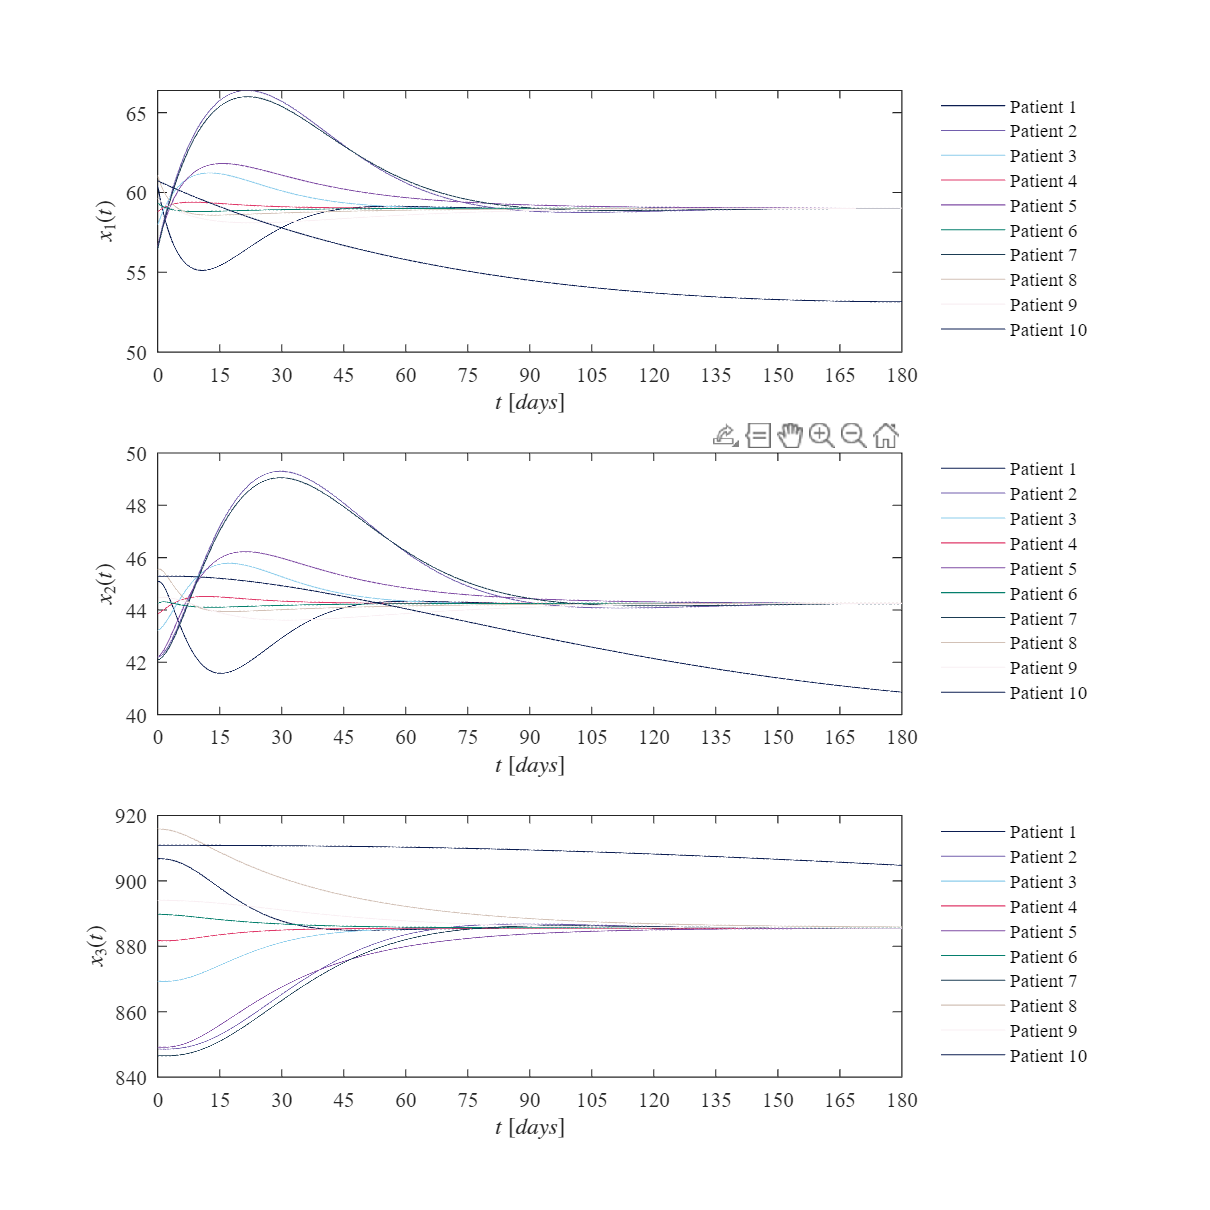

u = zeros(n+1, 1);
fig = 1; 
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i), beta(i),gamma(i),u,dt,tend); 
    plotdata (t,x1,x2,x3,fig)
end

## Caso: Con Transfuncion Sanguinia 

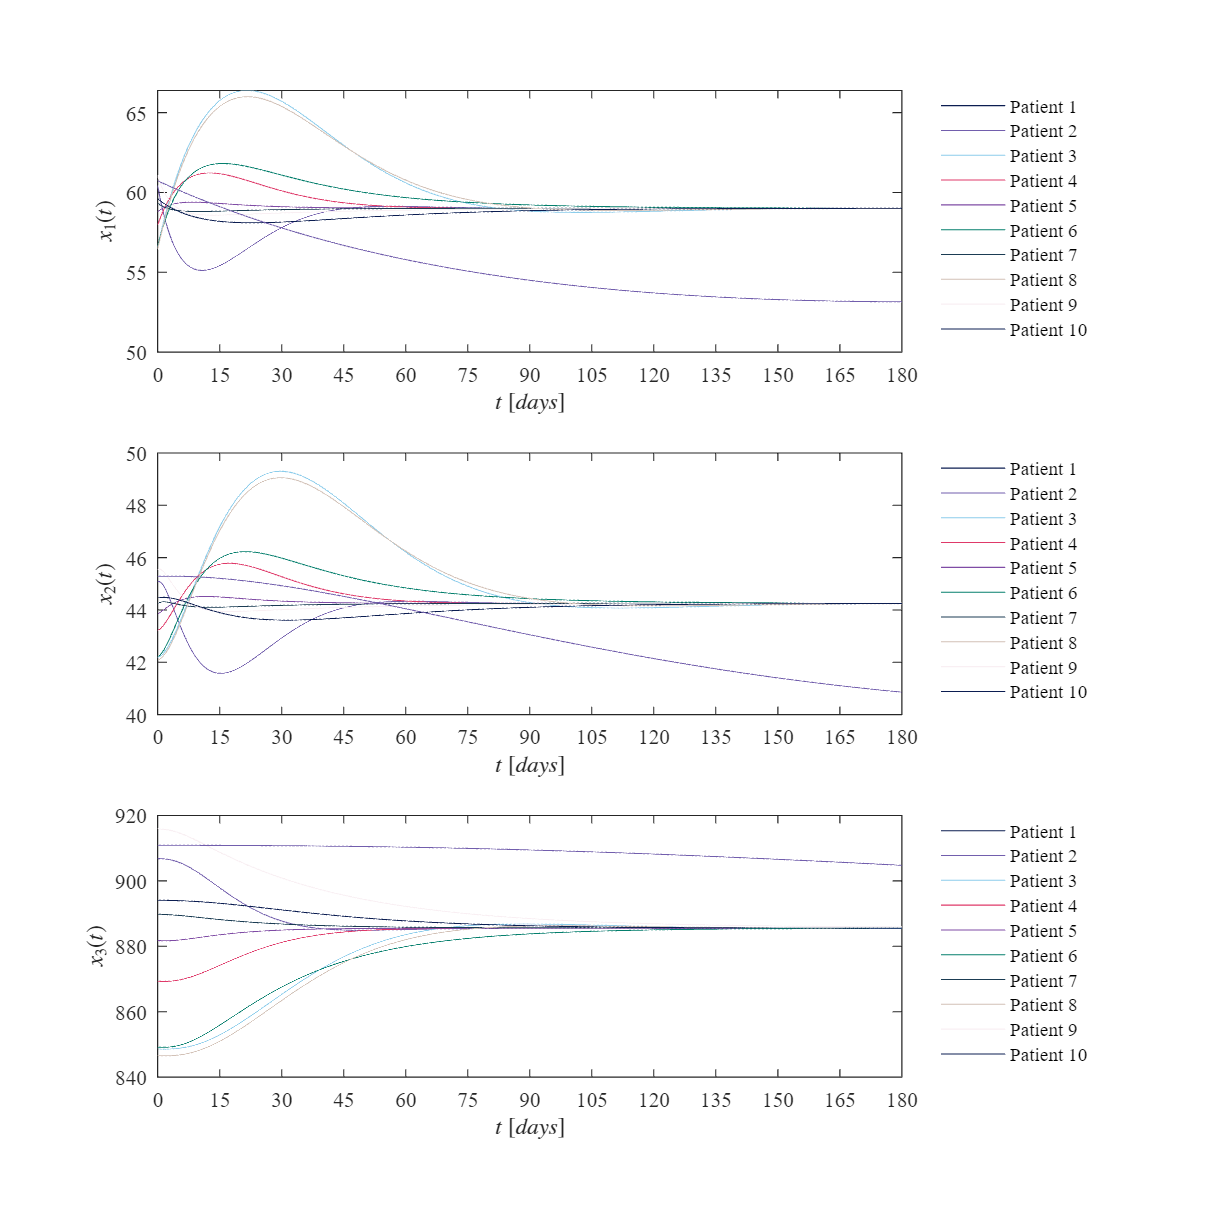

u = zeros(n+1, 1);
fig = 2; 
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i), beta(i),gamma(i),u,dt,tend); 
    plotdata (t,x1,x2,x3,fig)
end

## Funciones  

## Modelo Mtematico


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\dot{x} }_2 =\;\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\;\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0 ,beta ,gamma ,u ,dt ,tend)
%parametros fijos 
Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833; 
t = (0:dt:tend)'; 
n = round (tend/dt); 
x1 = zeros(n+1,1); x1(1) = x1_0; 
x2 = zeros(n+1,1); x2(1) = x2_0; 
x3 = zeros(n+1,1); x3(1) = x3_0; 
 for i = 1:n
     x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)* dt; 
     x2(i+1) = x2(i) + (beta*(k1*x1(i) - k2*x2(i)))*dt; 
     x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) -u(i)*x3(i))*dt;

 end
end

## Soluciones en el tiempo

function plotdata (t,x1,x2,x3,fig) 
set(figure(fig),'Color','w') 
set (gcf,'units', 'Centimeters' , 'Position',[1,1,20,20]);

  mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83; 
                210, 193, 182; 
                249, 239, 243;
                ]/255;


   
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x1); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_1(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x2); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_2(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x3); 
    xlabel('$t$ $[days]$', 'Interpreter','latex', 'FontSize', 10);
    ylabel('$x_3(t)$', 'Interpreter','latex', 'FontSize', 10);
    xlim([0 180]); xticks(0:15:180);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    L = legend ('Patient 1' , 'Patient 2' , 'Patient 3' , 'Patient 4' , 'Patient 5',...
        'Patient 6' , 'Patient 7' , 'Patient 8' , 'Patient 9' , 'Patient 10');
    set(L, 'FontSize', 9,'Box', 'Off', 'Location', 'NorthEastOutside');

    if fig ==1
        exportgraphics(gcf, 'Caso Sin transfusion.pdf', 'ContentType', 'Vector')
    elseif fig ==2
        exportgraphics(gcf, 'Caso Con transfusion.pdf', 'ContentType', 'Vector')
      end
   
end

